# **Deep Learning for Signal Data**

**This demo shows how you can build a model using transfer learning techniques to classify signal data. We will use Wavelet Transform to generate a time-frequency representation of a signal.  **

**The Wavelet Transform greatly enhances the spectral information present as a function of time in the signal and we can save this information as a Image**

# **Steps**:

- **Explore the Signals**

- **Generate Wavelet Time-Frequency Representations**

- **Train a Pre-Trained Network (AlexNet)**

- **Evaluate the trained model**

# **Explore the Signals**

## Load Signals

%% I am adding some comments to my file
load ECGData.mat;

size(ECGData.Data)

## Visualize Signals 

signalAnalyzer

## 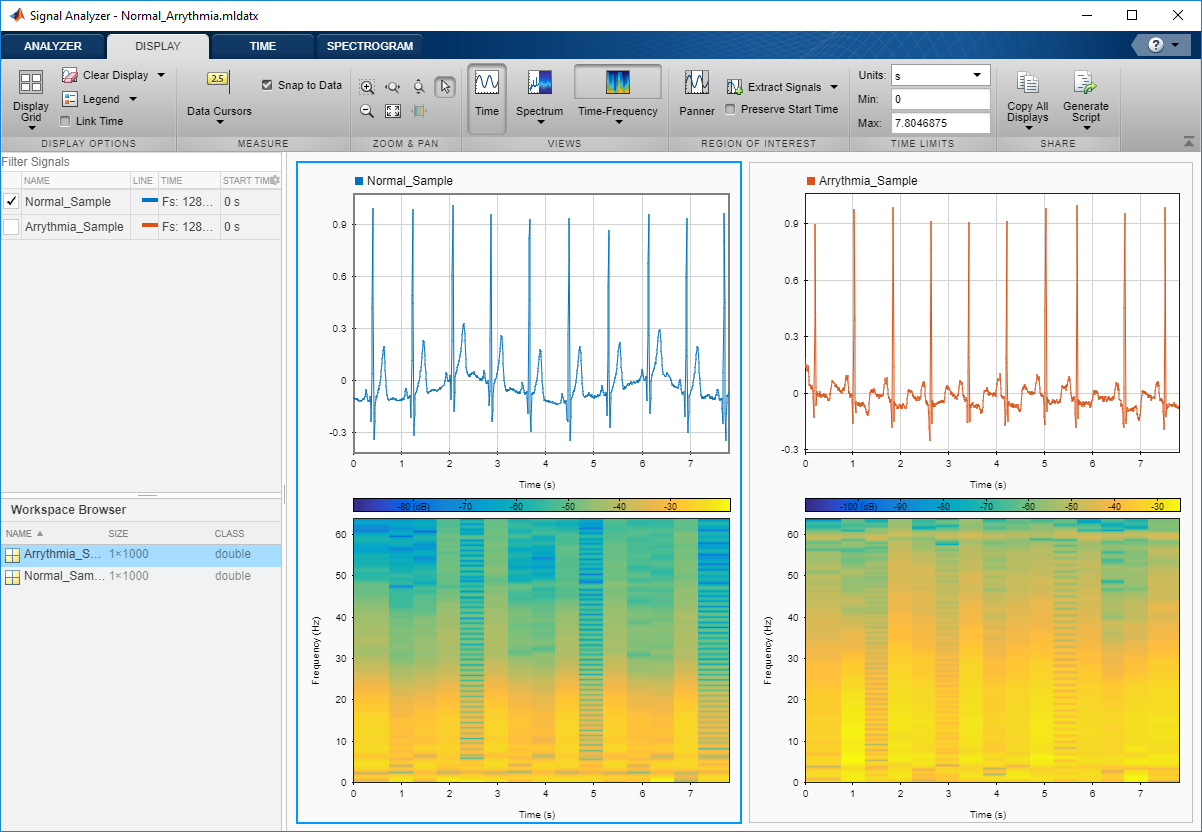

## Challenges with Traditional Time Frequency Analysis Approach

Fs = 128;
figure;
spectrogram(Normal_Sample,[],[],[],Fs,'yaxis'); title('Normal Signal');
figure;
spectrogram(Arrythmia_Sample,[],[],[],Fs,'yaxis'); title('Arrythmia Signal');


Notice although the signals have different meaning, a traditional time-frequency anlaysis doesnot help identify the difference between the two signals

##  Time Frequency Analysis using Wavelets

figure;
cwt(Normal_Sample,Fs); title('Normal Signal');
figure;
cwt(Arrythmia_Sample,Fs); title('Arrythmia Signal');

Notice how the spectral details have been enhanced with the Wavelet Transform. For instance,  

- The peaks are well separated 

- The irregular separation of the yellow bars distinguishes the  Arrythmia Signal from the Normal Signal

- There is some activity going on in the lower half of the representation for Arrythmia which is not the case with the Normal Signal

**We can save these representations as images (.jpg) and train a preconfigured Convolutional Neural Network**

# **Generate Wavelet Time-Frequency Representations**

## Create a Filter Bank

If we want to compute the wavelet transform on multiple signals, using a precomputed filter bank  can greatly speed up the process 

sig =ECGData.Data(1,:);
signalLength = length(sig);
Fs = 128;
fb = cwtfilterbank('SignalLength',signalLength,'SamplingFrequency',Fs,'VoicesPerOctave',48);


## Compute the Wavelet Transform 

[wt,f] = fb.wt(sig);

**Generate Time-Frequency Visualizations for all Signals**

type('saveTimeFrequencyRep.m')
implay('tf.mp4');

## Split the Time-Frequency Representation Images into Training and Test Sets

rootFolder = pwd;
folderName = 'data';

allImages = imageDatastore(strcat(rootFolder,filesep,folderName), 'IncludeSubfolders', true,...
    'LabelSource', 'foldernames');

[trainingImages, testImages] = splitEachLabel(allImages, 0.8, 'randomize');


# **Train a Pre-Trained Network (AlexNet)**

## **Initialize the Network **

load alexnet; 
layers = alex.Layers;
layers(23) = fullyConnectedLayer(3); % change this based on # of classes
layers(25) = classificationLayer;

## **Train the network**

ilr = 0.0001;
mxEpochs = 12;
mbSize =10;
opts = trainingOptions('sgdm', 'InitialLearnRate', ilr, ...
    'MaxEpochs',mxEpochs , 'MiniBatchSize',mbSize, ...
    'Plots', 'training-progress');

trainingImages.ReadFcn = @readFunctionTrain;

% myNet = trainNetwork(trainingImages, layers, opts);

implay('training.mp4');


[](http://\\fs-58-ah\vmgr$\home08\kdevleke\Documents\MATLAB\Deep-Learning-for-Signals\tf.mp4)

# **Evaluate the Trained Model**

testImages.ReadFcn = @readFunctionTrain;
predictedLabels = classify(myNet, testImages);
accuracy = mean(predictedLabels == testImages.Labels)
[confmat, order] = confusionmat(testImages.Labels,predictedLabels);
figure
heatmap(order,order,confmat);
title('Confusion Matrix')